# Rotations and the Spin $\frac{1}{2}$ Particle in a Magnetic Field

**Definition (Spinor representation)**. The spinor representation of Spin(3) =SU(2) is the representation on $C^2$ given by

                        g ∈ SU(2) → $\pi _{spinor}$(g) = g 

Elements of the representation space $C^2$ are called “spinors.”

**7.2 The spin **$\frac{1}{2}$** particle in a magnetic field**

we take as a standard basis for the Lie algebra su(2) the operators $X_j$, j = 1, 2, 3, where

                   
$$X_j=-i\frac{\sigma_j}{2}\rightarrow e^{\theta X_j}\in SU(2)$$


                   
$$S_j=\frac{\sigma_j}{2}\rightarrow e^{-i \theta S_j}\in SU(2)$$


In general,

    $\Omega(\theta,w)=e^{-i \theta w \cdot S} =e^{\theta w \cdot X} \in SU(2)$ where $\theta$ is the rotation angle and $w$ is the rotation axis.

$\Omega (\theta ,w) \in  SU(2)$ acts on the states as

                
$$|\psi > \to  \Omega (\theta ,w)|\psi >$$


Its Ad representation is 

                
$$S^{'}_j = \Omega (\theta ,w)S_j \Omega (\theta ,w)^{-1$$


as usual.

**7.3 The Heisenberg picture**

As we know

        
$$|\psi (t)> = U(t)|\psi (0)>$$


and expectation value of $O$ is given by

        
$$<\Psi(t)|O|\Psi(t)>=<\Psi(0)|U^{-1}(t)OU(t)|\Psi(0)>$$


In Heisenberg picture we put the time-dependence in observables and define the operator as

        
$$O_H(t)=U^{-1}(t)OU(t)$$
         
$$@U(t)=e^{-iHt}$$


So

        
$$\frac{d}{dt}O_H(t) = [iH,O_H(t)] = i[H,O_H(t)]$$


**7.4 Complex projective space**

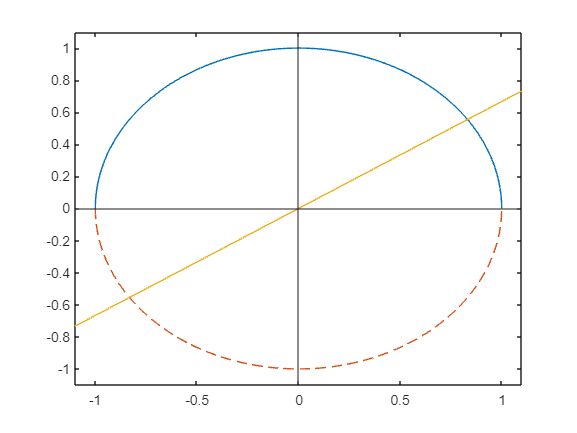


    fplot(@(x) sqrt(1-x.^2),[-1 1])
    hold on
    fplot(@(x) -sqrt(1-x.^2),[-1 1],'--')
    axis([-1.1 1.1 -1.1 1.1])
    xline(0)
    yline(0)
    fplot(@(x) 2*x/3)
    hold off

We can project the top half of the unit sphere to complex plane. A line through the north pole of the sphere and a point on the sphere will intersect a point on complex plane. So we can identify each point on the sphere to a point on the complex plane.

If $(x_1,x_2,x_3)$is a point on unit sphere we can identify it with a point on complex plane as


$$(x_1,x_2,x_3) \rightarrow x+iy \ \ \ @x=\frac{x_1}{1-x_3}, \ y=\frac{x_2}{1-x_3}$$


and


$$x+iy\rightarrow(x_1,x_2,x_3) \ \ \ @ \ x1=\frac{2x}{x^2+y^2+1}, \ x2=\frac{2y}{x^2+y^2+1}, \ x3=\frac{x^2+y^2-1}{x^2+y^2+1}$$


    zz=.5;
for k=linspace(-sqrt(1-zz^2),sqrt(1-zz^2),50)
    [x y z] = sphere(128);
    h = surfl(x, y, z); 
    set(h, 'FaceAlpha', 0.5)
    shading interp
    hold on
    plot3(0,0,0,'.','MarkerSize',15,'Color','k')
    axis([-2 2 -2 2 -2 2])
    grid off
    axis off
    
    [x y]=meshgrid(-2:.2:2);
    z=0*x;
    h2=surf(x,y,z);
    set(h2, 'FaceAlpha', 0.2)
    shading interp
    xline(0)
    yline(0)
    
    z1=zz;
    y1=k;
    x1=sqrt(1-z1^2-y1^2);
    
    
    x2=x1/(1-z1);
    y2=y1/(1-z1);
    z2=0;
    
    plot3([0 x1 x2],[0 y1 y2],[1 z1 z2],'.','MarkerSize',15,'Color','k')
    line([0 x1 x2],[0 y1 y2],[1 z1 z2])
    text(0,-2,0,'iR')
    text(-2,0,0,'R')
    text(1,-1,0,'C')
    text(x2,y2,z2,string(x2)+'+i'+string(y2))
    pause(.5)
    hold off
end

**7.5 The Bloch sphere**

If we map $R^3$ to $\sigma$ basis


$$x\rightarrow\sigma \cdot x$$


[s1 s2 s3]=Pauli();
S1=s1/2; S2=s2/2; S3=s3/2;
syms x [1 3] real
sx=x1*s1+x2*s2+x3*s3

$$sx = \left(\begin{array}{cc} x_{3} & x_{1}-x_{2}\,\mathrm{i}\\ x_{1}+x_{2}\,\mathrm{i} & -x_{3} \end{array}\right)$$

[evec eval]=eig(sx);
evec=simplify(subs(evec,x1^2+x2^2,1-x3^2))

$$evec = \left(\begin{array}{cc} \frac{x_{3}\,\mathrm{i}+\mathrm{i}}{-x_{2}+x_{1}\,\mathrm{i}} & \frac{\left(x_{1}-x_{2}\,\mathrm{i}\right)\,\left(x_{3}-1\right)}{{x_{1}}^{2}+{x_{2}}^{2}}\\ 1 & 1 \end{array}\right)$$

eval=subs(eval,x1^2+x2^2,1-x3^2)

$$eval = \left(\begin{array}{cc} 1 & 0\\ 0 & -1 \end{array}\right)$$

If we limit this to unit sphere $S^2$ $(x_1^2+x_2^2+x_3^2)$ then every $\sigma \cdot x$ has $\pm 1$as eigenvalues. Thus,


$$(\sigma \cdot x)u(x)=\pm u(x)$$



$$(\sigma \cdot x)u(x)=u(x) \rightarrow u_{+}(x)=\frac{1}{\sqrt{2(1+x_3}}\pmatrix{1+x_3 \cr x_1+ix_2}=\pmatrix{cos(\theta/2) \cr e^{i\phi}sin(\theta/2)}$$



$$(\sigma \cdot x)u(x)=-u(x) \rightarrow u_{-}(x)=\frac{1}{\sqrt{2(1+x_3}}\pmatrix{-(x_1+ix_2) \cr 1+x_3}=\pmatrix{ -e^{-i\phi}sin(\theta/2) \cr cos(\theta/2) }$$



$$u_{+}(x)^{\dagger}u_{-}(x)=0$$


**8.2 Representations of SU(2): construction**

Recall from equation 1.3 that if one has an action of a group on a space M, one can get a representation on functions f on M by taking

        $(\pi (g)f)(x) = f(g^{-1} \cdot  x)$        $@ \cdot$ is the group action, not inner product

Definition (Homogeneous polynomials). The complex vector space of homogeneous polynomials of degree n in two complex variables $z_1, z_2$ is the space of functions on $C^2$ of the form

###        
$$<z_1,z_2|f>=f(z_1, z_2) = a_0z_1^n + a_1z_1^{n-1}z_2 + \cdot  \cdot  \cdot  + a_{n-1}z_1z_2^{n-1} + a_nz_2^n$$


The space of such functions is a complex vector space of dimension n + 1.

SU(2) is defined on $C^2$ and this space of functions are on $C^2$, so this is the representation space of SU(2).

"""

Note that when working with vectors as linear combinations of basis vectors, we can use matrix notation to write a linear transformation as follows:


$$eLv=(e_1 \ \dots \ e_n)\pmatrix{L_{11} & L_{12}& \dots & L_{1n} \cr L_{21} & L_{22}& \dots & L_{2n} \cr \vdots &\vdots& \vdots & \vdots \cr L_{n1} & L_{n2}& \dots & L_{nn}} \pmatrix{v_1 \cr v_2 \cr \vdots \cr v_n} = (L^Te^T)^Tv$$


Thus, basis vector transform as


$$\pmatrix{e_1 \cr e_2 \cr \vdots \cr e_n} \rightarrow \pmatrix{L_{11} & L_{21}& \dots & L_{n1} \cr L_{12} & L_{22}& \dots & L_{n2} \cr \vdots &\vdots& \vdots & \vdots \cr L_{1n} & L_{2n}& \dots & L_{nn}} \pmatrix{e_1 \cr e_2 \cr \vdots \cr e_n}=L^Te^T$$



$$<\alpha|\beta>=<\alpha|L^{-1}L|\beta>=\sum_j <\alpha|L^{-1}|j><j|L|\beta>$$


"""

If we take

                
$$g=\pmatrix{\alpha & \beta \cr \gamma & \delta} \in GL(2,C)$$


and define the action of this on column vectors $z\in C^2$ by

                
$$g^{-1}z\rightarrow <z|z>=<z|gg^{-1}|z>$$


the action on function space becomes

            
$$f(g\cdot z)\rightarrow g \cdot z= <z|g= (z_1 \ z_2)g \equiv g^T \pmatrix{z_1 \cr z_2}=\pmatrix{\alpha & \beta \cr \gamma & \delta}^T\pmatrix{z_1 \cr z_2}=\pmatrix{\alpha z_1+\gamma z_2 \cr \beta z_1 +\delta z_2}$$


The representation πn(g) on homogeneous polynomial functions will be given by replacing

              
$$z_1 \to  \alpha z_1 + \gamma z_2, z_2 \to  \beta z_1 + \delta z_2$$



$$g=e^{tX} \rightarrow <z|g = <z|e^{tX}=(z_1 \ z_2)e^{tX}=z(t) \leftrightarrow f(z)\rightarrow f((z_1 \ z_2)e^{tX})=f(z_1(t) \ z_2(t))$$


Taking the derivative, the Lie algebra representation is given by


$$@ \frac{d}{dt}(z_1(t) \ z_2(t))_{t=0}=\frac{d}{dt}((z_1 \ z_2)e^{tX})_{t=0}=(z_1 \ z_2)X$$



$$\frac{d}{dt}f(z_1(t) \ z_2(t))_{t=0}=(\frac{\partial f}{\partial z_1}\frac{\partial z_1}{\partial t}+\frac{\partial f}{\partial z_2}\frac{\partial z_2}{\partial t})_{t=0}=\frac{\partial f}{\partial z_1}(X_{11}z_1+X_{21}z_2)+\frac{\partial f}{\partial z_2}(X_{12}z_1+X_{22}z_2)$$
       

Here $(z_1(t) \ z_2(t))=(z_1 \ z_2)e^{tX}\rightarrow (z_1(0) \ z_2(0))=(z_1 \ z_2)$

syms z [1 2]
syms f(z1,z2)
syms X [2 2]
syms t

s=simplify(z*expm(t*X));
simplify(subs(diff(s,t),t,0))

$$ans = \left(\begin{array}{cc} X_{1,1}\,z_{1}+X_{2,1}\,z_{2} & X_{1,2}\,z_{1}+X_{2,2}\,z_{2} \end{array}\right)$$

# Chapter 9

# Tensor Products, Entanglement, and Addition of Spin

**9.1 Tensor products**


$$V\otimes W=\pmatrix{V_{11}W &V_{12}W \cr V_{21}W &V_{22}W}$$



$$(A\otimes B)(v \otimes w)=Av \otimes Bw$$


syms A B [2 2]
syms a b [2 1]
T1=simplify(kron(A,B)*kron(a,b))

$$T1 = \left(\begin{array}{c} \left(A_{1,1}\,a_{1}+A_{1,2}\,a_{2}\right)\,\left(B_{1,1}\,b_{1}+B_{1,2}\,b_{2}\right)\\ \left(A_{1,1}\,a_{1}+A_{1,2}\,a_{2}\right)\,\left(B_{2,1}\,b_{1}+B_{2,2}\,b_{2}\right)\\ \left(A_{2,1}\,a_{1}+A_{2,2}\,a_{2}\right)\,\left(B_{1,1}\,b_{1}+B_{1,2}\,b_{2}\right)\\ \left(A_{2,1}\,a_{1}+A_{2,2}\,a_{2}\right)\,\left(B_{2,1}\,b_{1}+B_{2,2}\,b_{2}\right) \end{array}\right)$$

T2=kron(A*a,B*b)

$$T2 = \left(\begin{array}{c} \left(A_{1,1}\,a_{1}+A_{1,2}\,a_{2}\right)\,\left(B_{1,1}\,b_{1}+B_{1,2}\,b_{2}\right)\\ \left(A_{1,1}\,a_{1}+A_{1,2}\,a_{2}\right)\,\left(B_{2,1}\,b_{1}+B_{2,2}\,b_{2}\right)\\ \left(A_{2,1}\,a_{1}+A_{2,2}\,a_{2}\right)\,\left(B_{1,1}\,b_{1}+B_{1,2}\,b_{2}\right)\\ \left(A_{2,1}\,a_{1}+A_{2,2}\,a_{2}\right)\,\left(B_{2,1}\,b_{1}+B_{2,2}\,b_{2}\right) \end{array}\right)$$

isequal(T1,T2)

ans = logical
   1


**9.2 Composite quantum systems and tensor products**

syms H H1 H2 H3 H4 A B [2 2]
syms v w [2 1]
I=sym(eye(2))

$$I = \left(\begin{array}{cc} 1 & 0\\ 0 & 1 \end{array}\right)$$

HH=kron(H1,H2)

$$HH = \left(\begin{array}{cccc} H_{11,1}\,H_{21,1} & H_{11,1}\,H_{21,2} & H_{11,2}\,H_{21,1} & H_{11,2}\,H_{21,2}\\ H_{11,1}\,H_{22,1} & H_{11,1}\,H_{22,2} & H_{11,2}\,H_{22,1} & H_{11,2}\,H_{22,2}\\ H_{12,1}\,H_{21,1} & H_{12,1}\,H_{21,2} & H_{12,2}\,H_{21,1} & H_{12,2}\,H_{21,2}\\ H_{12,1}\,H_{22,1} & H_{12,1}\,H_{22,2} & H_{12,2}\,H_{22,1} & H_{12,2}\,H_{22,2} \end{array}\right)$$

kron(A,I)+kron(I,B)

$$ans = \left(\begin{array}{cccc} A_{1,1}+B_{1,1} & B_{1,2} & A_{1,2} & 0\\ B_{2,1} & A_{1,1}+B_{2,2} & 0 & A_{1,2}\\ A_{2,1} & 0 & A_{2,2}+B_{1,1} & B_{1,2}\\ 0 & A_{2,1} & B_{2,1} & A_{2,2}+B_{2,2} \end{array}\right)$$

kron(H,kron(H,H));

**9.4.1 Tensor products of SU(2) representations**

Theorem 9.1 (Clebsch–Gordan decomposition).

The tensor product $(\pi _{V^{n1}\otimes V^{n2}}, V^{n1} \otimes V^{n2} )$decomposes into irreducibles as


$$(\pi _{n_1+n_2}, V^{n_1+n_2} ) \oplus  (\pi _{n_1+n_2-2}, V^{n_1+n_2-2})\oplus \cdot  \cdot  \cdot \oplus (\pi _{|n_1-n_2|}, V^{|n_1-n_2|})$$


e.g.    

• Tensor product of two spinors:

    
$$V^1\otimes V^1=V^2\oplus V^0$$


J=su2rep(1/2)

J = 1×3 cell array
    {2×2 sym}    {2×2 sym}    {2×2 sym}


J{1}=-1i*J{1}

J = 1×3 cell array
    {2×2 sym}    {2×2 sym}    {2×2 sym}


J{1}

$$ans = \left(\begin{array}{cc} 0 & -\frac{1}{2}\,\mathrm{i}\\ -\frac{1}{2}\,\mathrm{i} & 0 \end{array}\right)$$



v1=sqrt(1/2)*[1;0];
v2=[0;1];
(kron(v1,v2)-kron(v2,v1))

ans =          0
    0.7071
   -0.7071
         0


kron(J{1}*v1,J{1}*v2)-kron(J{1}*v2,J{1}*v1)

$$ans = \left(\begin{array}{c} 0\\ \frac{\sqrt{2}}{8}\\ -\frac{\sqrt{2}}{8}\\ 0 \end{array}\right)$$

kron(v1,v2)

ans =          0
    0.7071
         0
         0


kron(J{1}*v1,J{1}*v2)

$$ans = \left(\begin{array}{c} 0\\ 0\\ -\frac{\sqrt{2}}{8}\\ 0 \end{array}\right)$$